# Problema 5

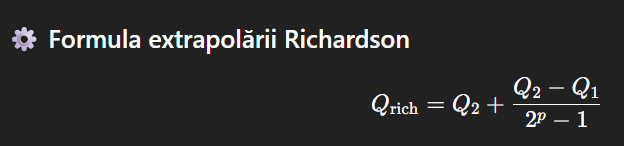

function rezultat = adquad_custom(f, a, b, tol)
% INPUT:
%   f    - functia de integrat (doar f(x), fara pondere)
%   a, b - capetele intervalului de integrare
%   tol  - toleranta dorita (ex: 1e-6)
%
% OUTPUT:
%   rezultat - valoarea aproximata a integralei ∫_a^b f(x) dx

    % Evaluam functia in capete si la mijloc
    fa = f(a);
    fb = f(b);
    fc = f((a + b) / 2);

    % Incepem procesul adaptiv de integrare
    rezultat = subdivide_quad(f, a, b, tol, fa, fc, fb);
end


function Q = subdivide_quad(f, a, b, tol, fa, fc, fb)
% INPUT (intern):
%   f    - functia de integrat
%   a, b - capetele intervalului curent
%   tol  - toleranta locala
%   fa   - f(a)
%   fc   - f((a + b)/2)
%   fb   - f(b)
%
% OUTPUT:
%   Q - valoarea aproximata a integralei pe [a, b] cu toleranta locala

    h = b - a;
    c = (a + b) / 2;
    d = (a + c) / 2;
    e = (c + b) / 2;

    % Evaluari suplimentare pentru rafinare
    fd = f(d);
    fe = f(e);

    % Aproximare grosiera: Simpson pe tot [a, b]
    Q1 = h / 6 * (fa + 4 * fc + fb);

    % Aproximare rafinata: Simpson pe [a, c] si [c, b]
    Q2 = h / 12 * (fa + 4 * fd + 2 * fc + 4 * fe + fb);

    % Verificam daca diferenta dintre estimari e suficient de mica
    if abs(Q2 - Q1) < 15 * tol
        % Extrapolare Richardson pentru corectare
        Q = Q2 + (Q2 - Q1) / 15;
    else
        % Impartim in doua si aplicam recursiv pe [a, c] si [c, b]
        Qa = subdivide_quad(f, a, c, tol/2, fa, fd, fc);
        Qb = subdivide_quad(f, c, b, tol/2, fc, fe, fb);
        Q = Qa + Qb;
    end
end


f = @(x) x.^2;   % functia de integrat
a = 0;
b = 1;
tol = 1e-6;      % precizia dorita

rezultat = adquad_custom(f, a, b, tol);

fprintf('Rezultat adquad: %.10f\n', rezultat);

Rezultat adquad: 0.3333333333


fprintf('Valoare exacta:  %.10f\n', 1/3);

Valoare exacta:  0.3333333333
